p = rand([3 1])*10;
k = rand([3 1]);
k = k/norm(k);
h = rand([3 1]);
h = h/norm(h);
theta = rand*2*pi-pi

theta = 2.2579


d = h'*rot(k,theta)*p;

subproblem4(h,p,k,d)

ans =    -0.9926
    2.2579



t = subproblem4_linear(h,p,k,d)

t =     2.2579   -0.9926


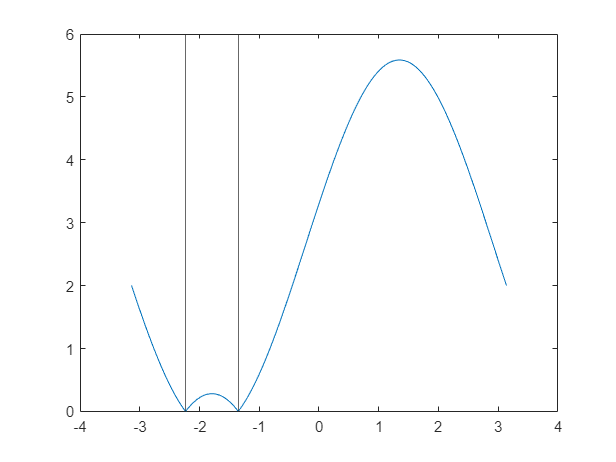

p = rand([3 1])*10;
k = rand([3 1]);
k = k/norm(k);
h = rand([3 1]);
h = h/norm(h);
d = abs(rand*10);

t = subproblem4_linear(h,p,k,d);

t_test = linspace(-pi, pi, 1000);
e_test = NaN(size(t_test));
for i = 1:length(t_test)
    e_test(i) = sp4_error(h, p, k, d, t_test(i));
end

plot(t_test, e_test);
xline(t(1));
if numel(t)>1
    xline(t(2));
end

function e = sp4_error(h, p, k, d, theta)
    e = abs(h' * rot(k, theta)*p - d);
end